# **Mono-Camera based Localizarion Model**

#### (Autonomous Vehicle Localization Using Onboard Sensors and HD-Geolocated Maps [MATLAB Project #20] - Spring 2024 Semester).

**Presented by: **

- Hazem Mohsen Abdelaziz 

- Yousra Adly Deifallah

#### Under Supervision of:

-  Prof. Dr. Mohamed Ibrahim Awad (Mechatronics Head Faculty of Engineering - Ain Shams University).

%Open 4 Mono_cameras Simulink Model
CamModelPath = 'C:\Users\Hazem Abdelaziz\Downloads\4_MonoCamera_based_Localization\4_MonoCamera_based_Localization\CameraLiveScript\cameraModel';  %Change the path according to the model path in your device 
open_system(CamModelPath);

%Set camera param and videa file path
%Mono_cameras parameters
fx = 1109; %Focal length in x-coordinate 
fy = 1109; %Focal length in y-coordinate 
cx = 640; %Principal point x-coordinate 
cy = 360; %principal point y-coordinate 

%Load vechile path 
dataT = load('D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Getting_Familiar_withToolboxes\threeVehiclesScene\refPosesT.mat');
dataX = load('D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Getting_Familiar_withToolboxes\threeVehiclesScene\refPosesX.mat');
dataY = load('D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Getting_Familiar_withToolboxes\threeVehiclesScene\refPosesY.mat');

%Get the data of X, Y and Yaw
refPosesT = dataT.refPosesT;
refPosesX = dataX.refPosesX;
refPosesY = dataY.refPosesY;

%Define file path of the videos
file_pathF = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\Video\monoF.avi';
file_pathB = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\Video\monoB.avi';
file_pathR = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\Video\monoR.avi';
file_pathL = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\Video\monoL.avi';

%Set the names of the videos in the Simulink model
set_param('cameraModel/VFront', 'Filename', file_pathF);
set_param('cameraModel/VBack', 'Filename', file_pathB);
set_param('cameraModel/VRight', 'Filename', file_pathR);
set_param('cameraModel/VLeft', 'Filename', file_pathL);

%Run Simulink Model
sim(CamModelPath);

%Convert video to frames 
convertVideoToFrames; %warning if the images directory exists 

Frames are stored in the foldersD:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Camera_based_Localization\MonoCameraFD:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Camera_based_Localization\MonoCameraBD:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Camera_based_Localization\MonoCameraRD:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Camera_based_Localization\MonoCameraL


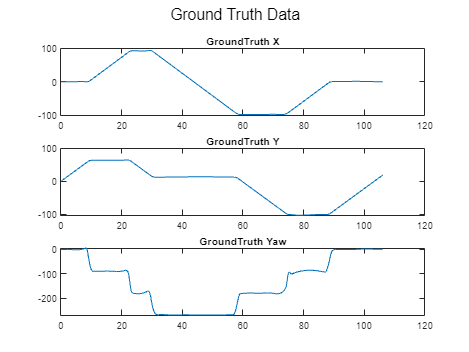

%Visualize groundtruth X, Y, and Yaw data.
timeVector = refPosesX(:,1); %Which is also consists of 500 element with deltaT = 0.21245(sec.)
refX = refPosesX(:,2)+17.5109; %Plot X data starting from X(0) = 0
refY = refPosesY(:,2)+11.1966; %Plot Y data starting from Y(0) = 0
refYaw = refPosesT(:,2)-89.6327; %Plot Yaw data starting from Yaw(0) = 0
figure;

%Creating subplots
subplot(3, 1, 1);
plot(timeVector, refX);
title('GroundTruth X');
 
 
subplot(3, 1, 2);
plot(timeVector, refY);
title('GroundTruth Y');
 
 
subplot(3, 1, 3);
plot(timeVector, refYaw);
title('GroundTruth Yaw');
sgtitle('Ground Truth Data'); 

%Absolute Velocity calculations 
distanceX = refPosesX(:,2); %X_distance
distanceY = refPosesY(:,2); %Y_distance

%Calculating the velocity using differentiation
dt = diff(timeVector); 
ddX = diff(distanceX); 
ddY = diff(distanceY);

Vx = [ddX(1) ./ dt(1); ddX ./ dt]; %Velocity in X_direction
Vy = [ddY(1) ./ dt(1); ddY ./ dt]; %Velocity in Y_direction

Vabs = (sqrt(Vx.^2 + Vy.^2)); %Absolute Velocity 
SF = Vabs/frameRate; %Scale Factor

%Creating cameraParams intrinsics
focalLength = [fx fy];
principalPoint = [cx cy];
cameraParams = cameraIntrinsics(focalLength, principalPoint, imageSize);

# **Front Camera Localizarion Model (On the Roof of the Vehicle)**

%Store Front Camera frames in vector
grayFolderPathF = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\MonoCameraF'; %The Front images folder path 

jpgFilesF = dir(fullfile(grayFolderPathF, '*.jpg'));
grayVectorF = cell(1, numel(jpgFilesF));

%Store Gray images in a vector
for i = 1:numel(jpgFilesF)
    %Construct the file path
    filePathF = fullfile(grayFolderPathF, jpgFilesF(i).name);
    %Read and store the images
    grayVectorF{i} = imread(filePathF);
end

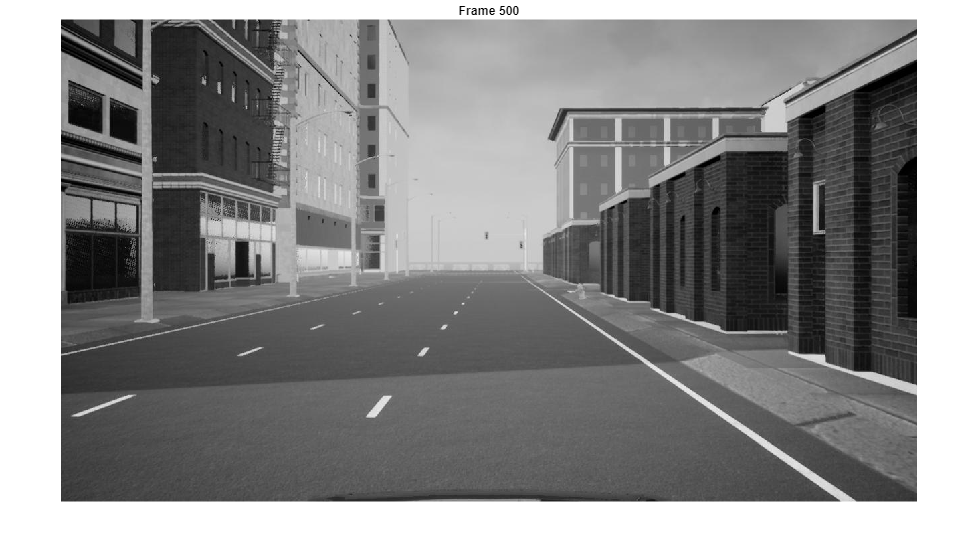

%This cell is to display the sequence of front gray images
for i = 1:numel(grayVectorF)
    %Display the current image
    imshow(grayVectorF{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

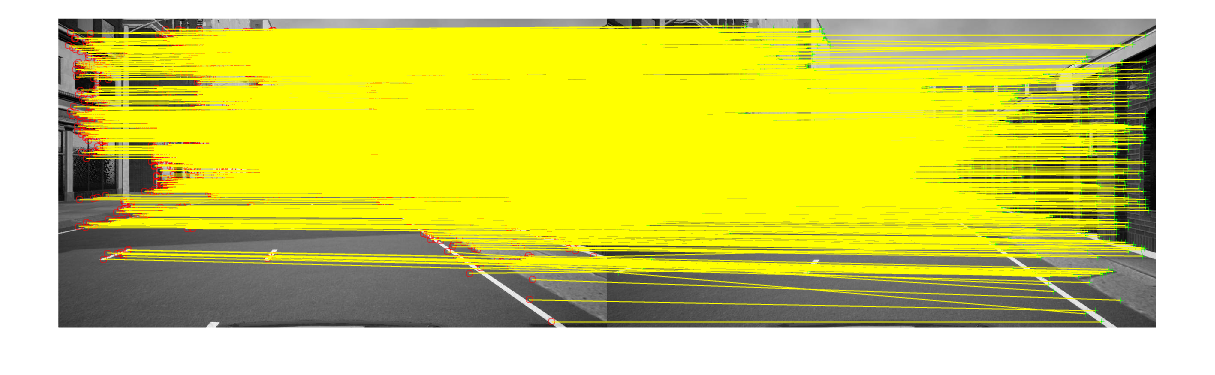

Matched Features in front frame 0
Matched Features in front frame 1
Matched Features in front frame 2
Matched Features in front frame 3
Matched Features in front frame 4
Matched Features in front frame 5
Matched Features in front frame 6
Matched Features in front frame 7
Matched Features in front frame 8
Matched Features in front frame 9
Matched Features in front frame 10
Matched Features in front frame 11
Matched Features in front frame 12
Matched Features in front frame 13
Matched Features in front frame 14
Matched Features in front frame 15
Matched Features in front frame 16
Matched Features in front frame 17
Matched Features in front frame 18
Matched Features in front frame 19
Matched Features in front frame 20
Matched Features in front frame 21
Matched Features in front frame 22
Matched Features in front frame 23
Matched Features in front frame 24
Matched Features in front frame 25
Matched Features in front frame 26
Matched Features in front frame 27
Matched Features in front fram

%Loop for saving front camera estimates
camXF = zeros(numel(jpgFilesF),1);
camYF = zeros(numel(jpgFilesF),1);
camYawF = zeros(numel(jpgFilesF),1);
camYawF(1) = deg2rad(refYaw(1));

figure;
for i = 1:numel(jpgFilesF) - 1

    grayFrame1F = grayVectorF{i};
    grayFrame2F = grayVectorF{i+1};

    %Detect and match features
    points1F = detectKAZEFeatures(grayFrame1F);
    points2F = detectKAZEFeatures(grayFrame2F);

    [features1F, points1F] = extractFeatures(grayFrame1F, points1F);
    [features2F, points2F] = extractFeatures(grayFrame2F, points2F);
    
    indexPairs = matchFeatures(features1F, features2F);
    
    matchedPoints1F = points1F(indexPairs(:, 1), :);
    matchedPoints2F = points2F(indexPairs(:, 2), :);

    %Estimate Essential matrix
    [eMatrix, inliers] = estimateEssentialMatrix(matchedPoints1F, matchedPoints2F, cameraParams);
    
    %Select inlier points
    inlierPoints1F = matchedPoints1F(inliers);
    inlierPoints2F = matchedPoints2F(inliers);

    %Estimate relative camera pose
    relPoseF = estrelpose(eMatrix, cameraParams, inlierPoints1F, inlierPoints2F);
    RotF = relPoseF.R;
    tF = relPoseF.Translation;

    %Visualize matched features
    showMatchedFeatures(grayFrame1F, grayFrame2F, inlierPoints1F, inlierPoints2F, 'montage');
    disp(['Matched Features in front frame ', num2str(i-1)]);
    eulerAngles = rotm2eul(RotF, 'XYZ');
    camYawF(i+1) = camYawF(i) - eulerAngles(2);
    camYF(i+1) = camYF(i) + tF(3)*cos(deg2rad(refYaw(i)))*SF(i) - tF(1)*cos((pi/2) -(deg2rad(refYaw(i))))*SF(i);
    camXF(i+1) = camXF(i) - tF(3)*sin(deg2rad(refYaw(i)))*SF(i) + tF(1)*sin(pi/2 -(deg2rad(refYaw(i))))*SF(i);
end

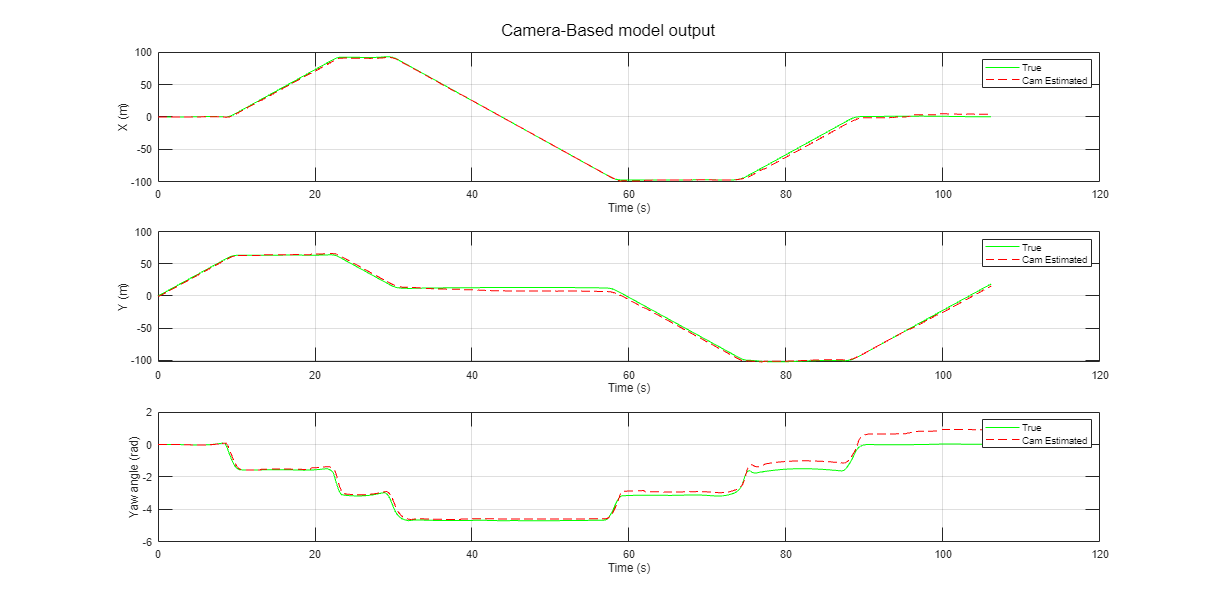

%Plot ground truth vs. Front camera estimation
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, refX, 'g');
hold on;
plot(timeVector, camXF, 'r--');
xlabel('Time (s)');
ylabel('X (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 2);
plot(timeVector, refY, 'g');
hold on;
plot(timeVector, camYF, 'r--');
xlabel('Time (s)');
ylabel('Y (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 3);
plot(timeVector, deg2rad(refYaw), 'g');
hold on;
plot(timeVector, camYawF, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('True', 'Cam Estimated');
grid on;
sgtitle('Camera-Based model output');

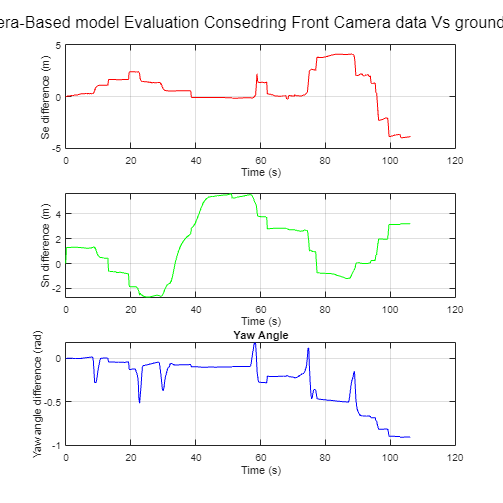

%Front Camera based error evaluation
%Calculating Error between Front Camera and ground truth
XDiffCamF = refX - camXF;
YDiffCamF = refY - camYF;
YawDiffCamF = deg2rad(refYaw) - camYawF;

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); %left bottom width height

subplot(3, 1, 1);
plot(timeVector, XDiffCamF, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, YDiffCamF, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, YawDiffCamF, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (rad)');
title('Yaw Angle')
grid on;

sgtitle('Camera-Based model Evaluation Consedring Front Camera data Vs ground truth');

# **Back Camera Localizarion Model (On the Roof of the Vehicle with offset in (X = -0.04m & Yaw = 180))**

%Store the back camera frames in vector
grayFolderPathB = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\MonoCameraB'; %The Back images folder path 
jpgFilesB = dir(fullfile(grayFolderPathB, '*.jpg'));
grayVectorB = cell(1, numel(jpgFilesB));

%Store Gray images in a image vector
for i = 1:numel(jpgFilesB)
    %Construct the full file path
    filePathB = fullfile(grayFolderPathB, jpgFilesB(i).name);
    %Read the image and store it
    grayVectorB{i} = imread(filePathB);
end

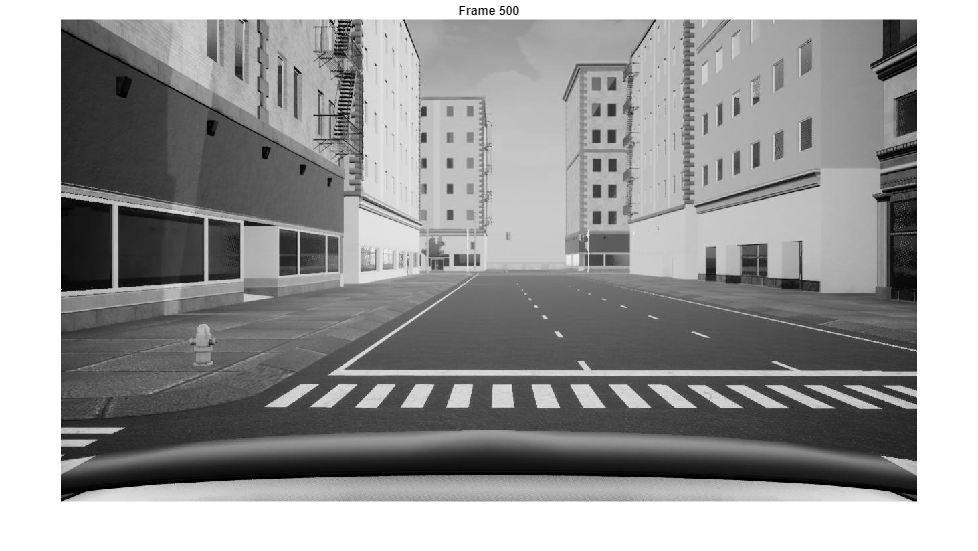

%This cell is to display the sequence of back gray image 
for i = 1:numel(grayVectorB)
    %Display the current image
    imshow(grayVectorB{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

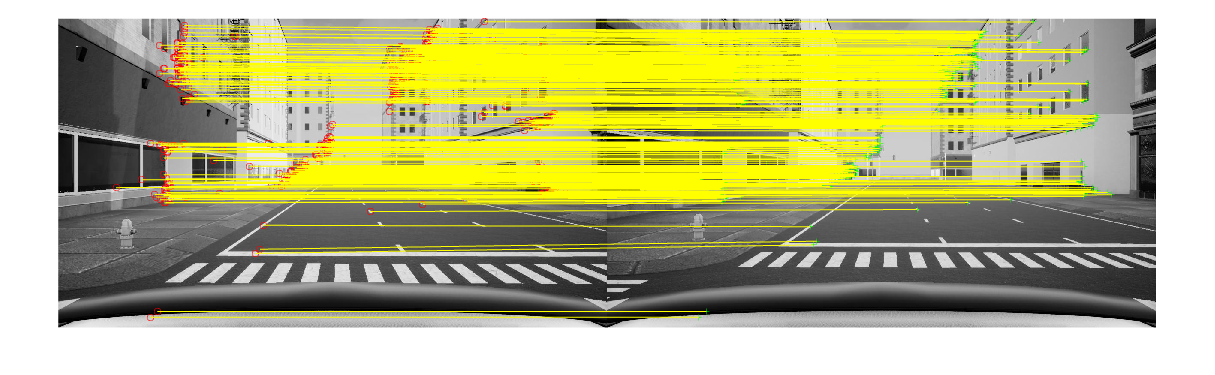

Matched Features in Back frame 0
Matched Features in Back frame 1
Matched Features in Back frame 2
Matched Features in Back frame 3
Matched Features in Back frame 4
Matched Features in Back frame 5
Matched Features in Back frame 6
Matched Features in Back frame 7
Matched Features in Back frame 8
Matched Features in Back frame 9
Matched Features in Back frame 10
Matched Features in Back frame 11
Matched Features in Back frame 12
Matched Features in Back frame 13
Matched Features in Back frame 14
Matched Features in Back frame 15
Matched Features in Back frame 16
Matched Features in Back frame 17
Matched Features in Back frame 18
Matched Features in Back frame 19
Matched Features in Back frame 20
Matched Features in Back frame 21
Matched Features in Back frame 22
Matched Features in Back frame 23
Matched Features in Back frame 24
Matched Features in Back frame 25
Matched Features in Back frame 26
Matched Features in Back frame 27
Matched Features in Back frame 28
Matched Features in Back

%Loop for saving the back camera estimates
camXB = zeros(numel(jpgFilesB),1);
camYB = zeros(numel(jpgFilesB),1);
camYawB = zeros(numel(jpgFilesB),1);
camYawB(1) = deg2rad(refYaw(1));

figure;
for i = 1:numel(jpgFilesB) - 1

    grayFrameB1 = grayVectorB{i};
    grayFrameB2 = grayVectorB{i+1};

    %Detect and match features
    pointsB1 = detectKAZEFeatures(grayFrameB1);
    pointsB2 = detectKAZEFeatures(grayFrameB2);
    
    [featuresB1, pointsB1] = extractFeatures(grayFrameB1, pointsB1);
    [featuresB2, pointsB2] = extractFeatures(grayFrameB2, pointsB2);
    
    indexPairs = matchFeatures(featuresB1, featuresB2);
    
    matchedPointsB1 = pointsB1(indexPairs(:, 1), :);
    matchedPointsB2 = pointsB2(indexPairs(:, 2), :);

    %Estimate Essential matrix
    [eMatrix, inliers] = estimateEssentialMatrix(matchedPointsB1, matchedPointsB2, cameraParams);
   
    % Select inlier points
    inlierPointsB1 = matchedPointsB1(inliers);
    inlierPointsB2 = matchedPointsB2(inliers);

    %Estimate relative camera pose
    relPoseB = estrelpose(eMatrix, cameraParams, inlierPointsB1, inlierPointsB2);
    RotB = relPoseB.R;
    tB = relPoseB.Translation;

    %Visualize matched features
    showMatchedFeatures(grayFrameB1, grayFrameB2, inlierPointsB1, inlierPointsB2, 'montage');
    disp(['Matched Features in Back frame ', num2str(i-1)]);
    eulerAngles = rotm2eul(RotB, 'XYZ');
    camYawB(i+1) = camYawB(i) - eulerAngles(2);
    camYB(i+1) = camYB(i) + tB(3)*cos(deg2rad(refYaw(i))+pi)*SF(i) - tB(1)*cos(-pi/2 -(deg2rad(refYaw(i))))*SF(i);
    camXB(i+1) = camXB(i) - tB(3)*sin(deg2rad(refYaw(i))+pi)*SF(i) + tB(1)*sin(-pi/2 -(deg2rad(refYaw(i))))*SF(i);
end

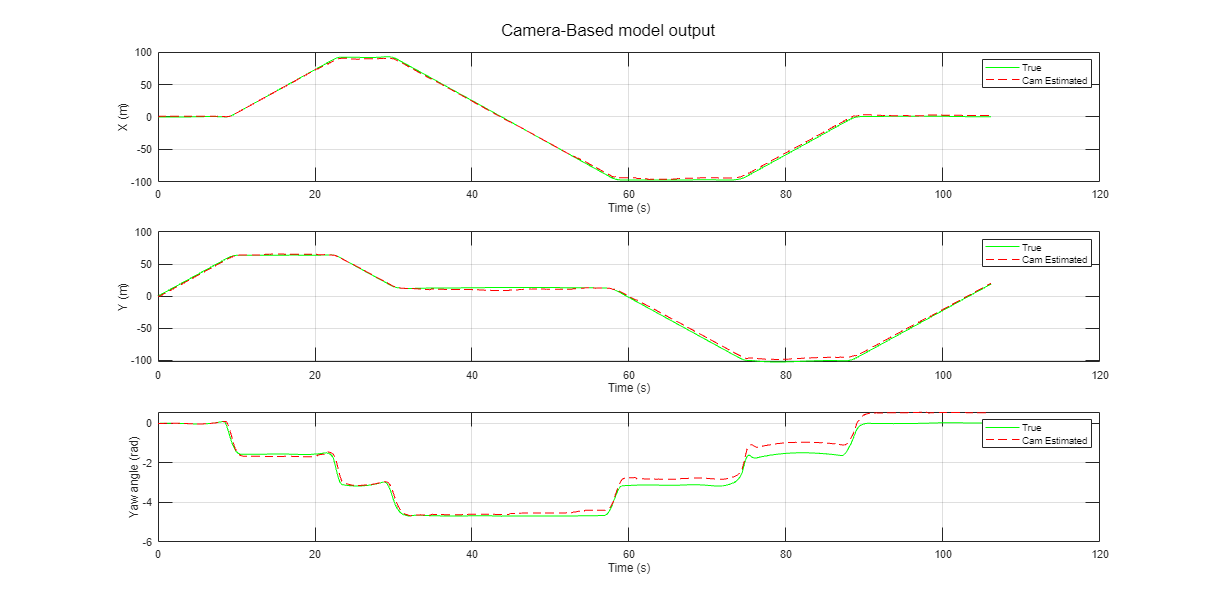

%Plot ground truth vs. back camera estimation
figure;
figure('Position', [50, 50, 2000, 1000]); 

subplot(3, 1, 1);
plot(timeVector, refX, 'g');
hold on;
plot(timeVector, camXB, 'r--');
xlabel('Time (s)');
ylabel('X (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 2);
plot(timeVector, refY, 'g');
hold on;
plot(timeVector, camYB, 'r--');
xlabel('Time (s)');
ylabel('Y (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 3);
plot(timeVector, deg2rad(refYaw), 'g');
hold on;
plot(timeVector, camYawB, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('True', 'Cam Estimated');
grid on;
sgtitle('Camera-Based model output');

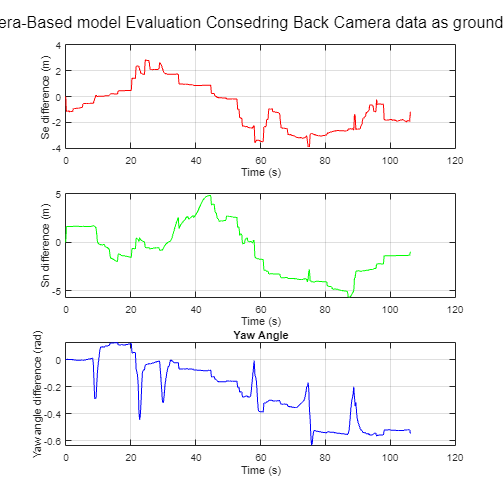

%Back Camera based error evaluation
%Calculating Error between Back Camera and ground truth
XDiffCamB = refX - camXB;
YDiffCamB = refY - camYB;
YawDiffCamB = deg2rad(refYaw) - camYawB;

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, XDiffCamB, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, YDiffCamB, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, YawDiffCamB, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (rad)');
title('Yaw Angle')
grid on;

sgtitle('Camera-Based model Evaluation Consedring Back Camera data as ground truth');

# **Left Camera Localizarion Model (On the Roof of the Vehicle with offset in (Y = -0.06m & Yaw = 90))**

%Store camera Left frames in vector
grayFolderPathL = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\MonoCameraL'; %The Left images folder path 

jpgFilesL = dir(fullfile(grayFolderPathL, '*.jpg'));
grayVectorL = cell(1, numel(jpgFilesL));

%Store Gray images in vector
for i = 1:numel(jpgFilesL)
    %Construct the file path
    filePathL = fullfile(grayFolderPathL, jpgFilesL(i).name);
    %Read and store the images
    grayVectorL{i} = imread(filePathL);
end

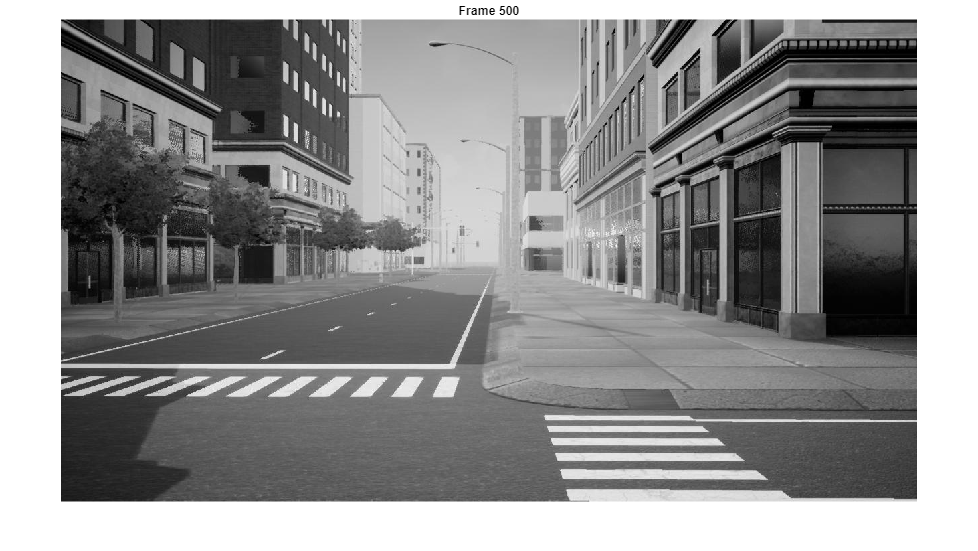

%This cell is to display the sequence of Left gray image
for i = 1:numel(grayVectorL)
    %Display the current image
    imshow(grayVectorL{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

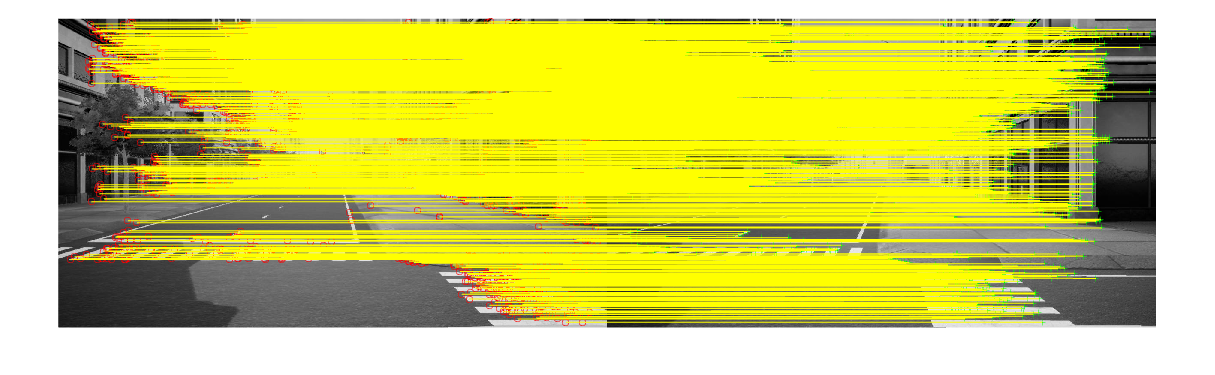

Matched Features in Left frame 0
Matched Features in Left frame 1
Matched Features in Left frame 2
Matched Features in Left frame 3
Matched Features in Left frame 4
Matched Features in Left frame 5
Matched Features in Left frame 6
Matched Features in Left frame 7
Matched Features in Left frame 8
Matched Features in Left frame 9
Matched Features in Left frame 10
Matched Features in Left frame 11
Matched Features in Left frame 12
Matched Features in Left frame 13
Matched Features in Left frame 14
Matched Features in Left frame 15
Matched Features in Left frame 16
Matched Features in Left frame 17
Matched Features in Left frame 18
Matched Features in Left frame 19
Matched Features in Left frame 20
Matched Features in Left frame 21
Matched Features in Left frame 22
Matched Features in Left frame 23
Matched Features in Left frame 24
Matched Features in Left frame 25
Matched Features in Left frame 26
Matched Features in Left frame 27
Matched Features in Left frame 28
Matched Features in Left

%Loop for saving left camera estimates
camXL = zeros(numel(jpgFilesL),1);
camYL = zeros(numel(jpgFilesL),1);
camYawL = zeros(numel(jpgFilesL),1);
camYawL(1) = deg2rad(refYaw(1));
figure;
for i = 1:numel(jpgFilesL) - 1

    grayFrame1L = grayVectorL{i};
    grayFrame2L = grayVectorL{i+1};

    %Detect and match features
    points1L = detectKAZEFeatures(grayFrame1L);
    points2L = detectKAZEFeatures(grayFrame2L);
    
    [features1L, points1L] = extractFeatures(grayFrame1L, points1L);
    [features2L, points2L] = extractFeatures(grayFrame2L, points2L);
    
    indexPairs = matchFeatures(features1L, features2L);
    
    matchedPoints1L = points1L(indexPairs(:, 1), :);
    matchedPoints2L = points2L(indexPairs(:, 2), :);

    %Estimate Essential matrix
    [eMatrix, inliers] = estimateEssentialMatrix(matchedPoints1L, matchedPoints2L, cameraParams);
    
    %Select inlier points
    inlierPoints1L = matchedPoints1L(inliers);
    inlierPoints2L = matchedPoints2L(inliers);

    %Estimate relative camera pose
    relPoseL = estrelpose(eMatrix, cameraParams, inlierPoints1L, inlierPoints2L);
    RotL = relPoseL.R;
    tL = relPoseL.Translation;

    %Visualize matched features
    showMatchedFeatures(grayFrame1L, grayFrame2L, inlierPoints1L, inlierPoints2L, 'montage');
    disp(['Matched Features in Left frame ', num2str(i-1)]);
    eulerAngles = rotm2eul(RotL, 'XYZ');
    camYawL(i+1) = camYawL(i) - eulerAngles(2);
    camYL(i+1) = camYL(i) + tL(3)*cos(deg2rad(refYaw(i))-pi/2)*SF(i) - tL(1)*cos(pi-(deg2rad(refYaw(i))))*SF(i);
    camXL(i+1) = camXL(i) + tL(3)*sin(deg2rad(refYaw(i))-pi/2)*SF(i) - tL(1)*sin(pi-(deg2rad(refYaw(i))))*SF(i);
end

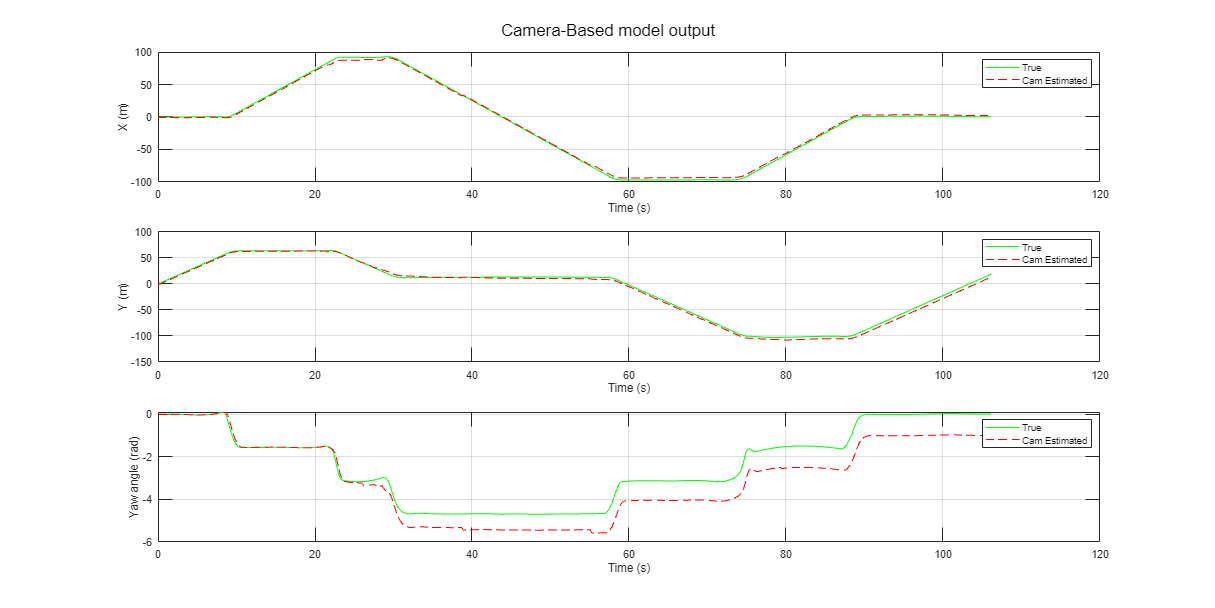

%Plot ground truth vs. left camera estimation
figure;
figure('Position', [50, 50, 2000, 1000]); 

subplot(3, 1, 1);
plot(timeVector, refX, 'g');
hold on;
plot(timeVector, camXL, 'r--');
xlabel('Time (s)');
ylabel('X (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 2);
plot(timeVector, refY, 'g');
hold on;
plot(timeVector, camYL, 'r--');
xlabel('Time (s)');
ylabel('Y (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 3);
plot(timeVector, deg2rad(refYaw), 'g');
hold on;
plot(timeVector, camYawL, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('True', 'Cam Estimated');
grid on;
sgtitle('Camera-Based model output');

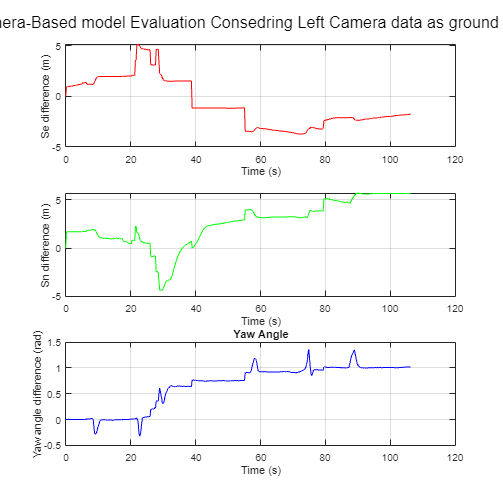

%Left Camera based error evaluation
%Calculating Error between Left Camera and ground truth
XDiffCamL = refX - camXL;
YDiffCamL = refY - camYL;
YawDiffCamL = deg2rad(refYaw) - camYawL;

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, XDiffCamL, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, YDiffCamL, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, YawDiffCamL, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (rad)');
title('Yaw Angle')
grid on;

sgtitle('Camera-Based model Evaluation Consedring Left Camera data as ground truth');

# **Right Camera Localizarion Model (On the Roof of the Vehicle with offset in (Y = 0.06m & Yaw = -90))**

%Store Right camera frames in vector
grayFolderPathR = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\MonoCamera_based_Localization\MonoCameraR'; %The Right images folder path 

jpgFilesR = dir(fullfile(grayFolderPathR, '*.jpg'));
grayVectorR = cell(1, numel(jpgFilesR));

%Store Gray images in a image vector
for i = 1:numel(jpgFilesR)
    %Construct the file path
    filePathR = fullfile(grayFolderPathR, jpgFilesR(i).name);
    %Read and store the images 
    grayVectorR{i} = imread(filePathR);
end

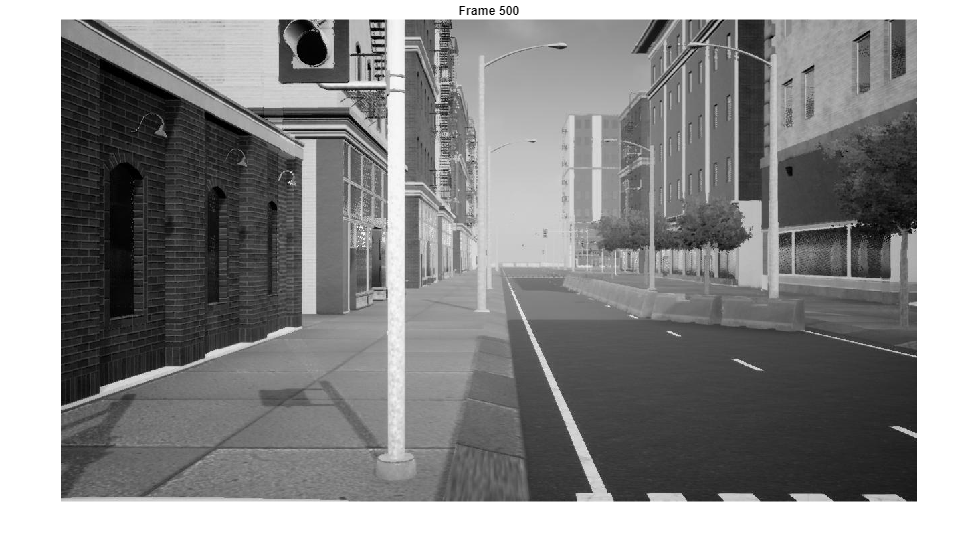

%This cell is to display the sequence of right gray image 
for i = 1:numel(grayVectorR)
    %Display the current image
    imshow(grayVectorR{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

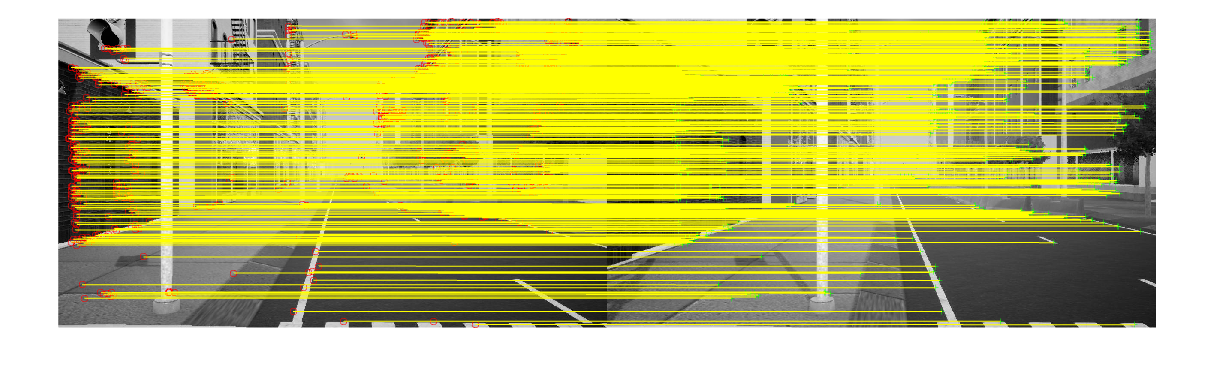

Matched Features in Right frame 0
Matched Features in Right frame 1
Matched Features in Right frame 2
Matched Features in Right frame 3
Matched Features in Right frame 4
Matched Features in Right frame 5
Matched Features in Right frame 6
Matched Features in Right frame 7
Matched Features in Right frame 8
Matched Features in Right frame 9
Matched Features in Right frame 10
Matched Features in Right frame 11
Matched Features in Right frame 12
Matched Features in Right frame 13
Matched Features in Right frame 14
Matched Features in Right frame 15
Matched Features in Right frame 16
Matched Features in Right frame 17
Matched Features in Right frame 18
Matched Features in Right frame 19
Matched Features in Right frame 20
Matched Features in Right frame 21
Matched Features in Right frame 22
Matched Features in Right frame 23
Matched Features in Right frame 24
Matched Features in Right frame 25
Matched Features in Right frame 26
Matched Features in Right frame 27
Matched Features in Right fram

Matched Features in Right frame 498


%Loop for saving right camera estimates
camXR = zeros(numel(jpgFilesR),1);
camYR = zeros(numel(jpgFilesR),1);
camYawR = zeros(numel(jpgFilesR),1);
camYawR(1) = deg2rad(refYaw(1));
figure;

for i = 1:numel(jpgFilesR) - 1

    grayFrame1R = grayVectorR{i};
    grayFrame2R = grayVectorR{i+1};

    %Detect and match features
    points1R = detectKAZEFeatures(grayFrame1R);
    points2R = detectKAZEFeatures(grayFrame2R);
    
    [features1R, points1R] = extractFeatures(grayFrame1R, points1R);
    [features2R, points2R] = extractFeatures(grayFrame2R, points2R);
    
    indexPairs = matchFeatures(features1R, features2R);
    
    matchedPoints1R = points1R(indexPairs(:, 1), :);
    matchedPoints2R = points2R(indexPairs(:, 2), :);

    %Estimate Essential matrix
    [eMatrix, inliers] = estimateEssentialMatrix(matchedPoints1R, matchedPoints2R, cameraParams);
    
    %Select inlier points
    inlierPoints1R = matchedPoints1R(inliers);
    inlierPoints2R = matchedPoints2R(inliers);

    %Estimate relative camera pose
    relPoseR = estrelpose(eMatrix, cameraParams, inlierPoints1R, inlierPoints2R);
    RotR = relPoseR.R;
    tR = relPoseR.Translation;

    %Visualize matched features
    showMatchedFeatures(grayFrame1R, grayFrame2R, inlierPoints1R, inlierPoints2R, 'montage');
    disp(['Matched Features in Right frame ', num2str(i-1)]);
    eulerAngles = rotm2eul(RotR, 'XYZ');
    camYawR(i+1) = camYawR(i) - eulerAngles(2);
    camYR(i+1) = camYR(i) + tR(3)*cos(deg2rad(refYaw(i))+pi/2)*SF(i) - tR(1)*cos(-(deg2rad(refYaw(i))))*SF(i);
    camXR(i+1) = camXR(i) + tR(3)*sin(deg2rad(refYaw(i))+pi/2)*SF(i) - tR(1)*sin(-(deg2rad(refYaw(i))))*SF(i);
end

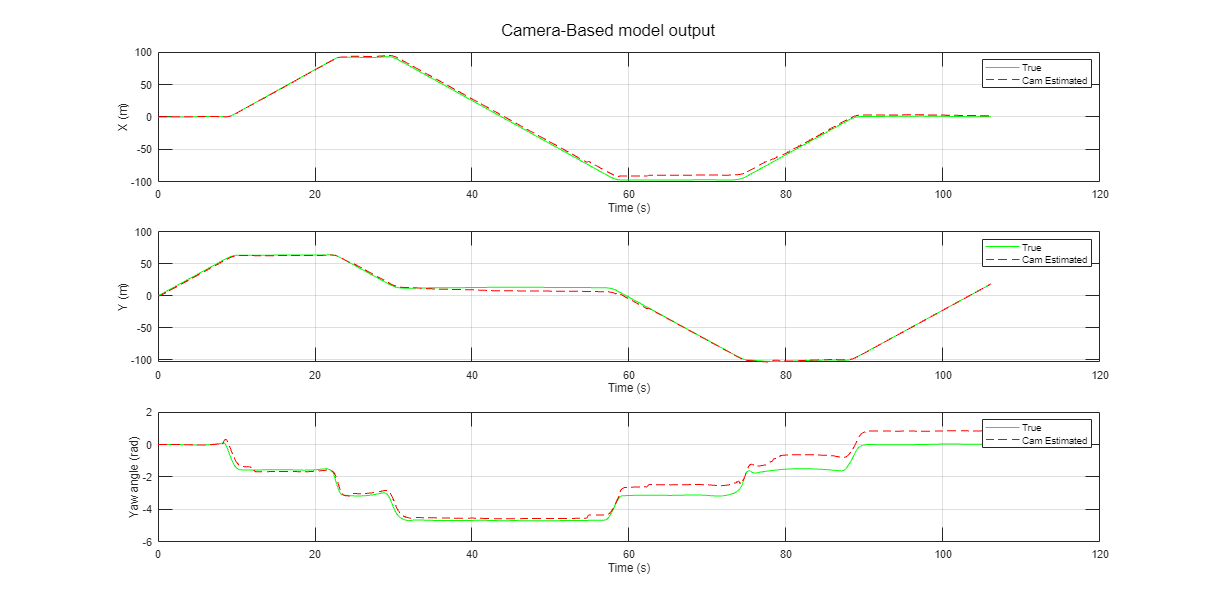

% 11. Plot ground truth vs. camera estimation
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, refX, 'g');
hold on;
plot(timeVector, camXR, 'r--');
xlabel('Time (s)');
ylabel('X (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 2);
plot(timeVector, refY, 'g');
hold on;
plot(timeVector, camYR, 'r--');
xlabel('Time (s)');
ylabel('Y (m)');
legend('True', 'Cam Estimated');
grid on;

subplot(3, 1, 3);
plot(timeVector, deg2rad(refYaw), 'g');
hold on;
plot(timeVector, camYawR, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('True', 'Cam Estimated');
grid on;
sgtitle('Camera-Based model output');

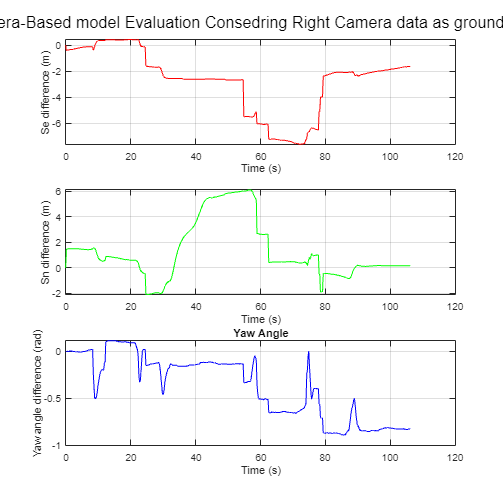

%Right Camera based error evaluation
%Calculating Error between Right Camera and ground truth
XDiffCamR = refX - camXR;
YDiffCamR = refY - camYR;
YawDiffCamR = deg2rad(refYaw) - camYawR;

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); 

subplot(3, 1, 1);
plot(timeVector, XDiffCamR, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, YDiffCamR, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, YawDiffCamR, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (rad)');
title('Yaw Angle')
grid on;

sgtitle('Camera-Based model Evaluation Consedring Right Camera data as ground truth');